close all; clear all;


pos10 = [-0.5;1.5];
pos20 = [0.5;1.5];

T1=5

T1 = 5

T2=1

T2 = 1



[t,pos] = ode45(@(t,pos) vdp(t,pos,T1,T2),[0:0.1 10],[pos10;pos20]);


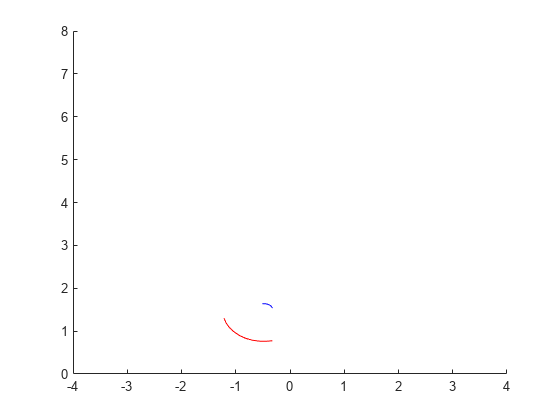

close all;
L1 = animatedline('color', 'b',MaximumNumPoints=10);
L2 = animatedline('color', 'r',MaximumNumPoints=10);

figure(1)
for K = 1 : size(pos,1)
    addpoints(L1, pos(K,1), pos(K,2) );
    addpoints(L2, pos(K,3), pos(K,4) );
    xlim([-4 4])
    ylim([0 8])
   drawnow update;
    pause(0.01)
  
end





function res = vdp(t,pos,T1,T2)
pos1 = pos(1:2);
pos2 = pos(3:4);
vel2 = vel(pos1,pos2,T1);
vel1 = vel(pos2,pos1,T2);
res = [vel1.vy;vel1.vz;vel2.vy;vel2.vz];
end


function res = vel(pos1,pos2,T1)
r1 = pos2-pos1;
rimage = pos1-[0;2*abs(pos1(2))];
R1 = pos2-(rimage);

v3 = T1*r1(1)/norm(r1)^3;
% 
 v3 =v3+  -T1*R1(1)/norm(R1)^3;
 v3 =v3+  6*T1*abs(pos1(2))*R1(1)*R1(2)/norm(R1)^5;
 v3 =v3+  -6*T1*R1(2)^2*R1(1)/norm(R1)^5;

v2 = -T1*r1(2)/norm(r1)^3;
% 
v2 =v2+ T1*R1(2)/norm(R1)^3;
v2 =v2+ -2*T1*abs(pos1(2))*(1/norm(R1)^3 -3*R1(1)^2/norm(R1)^5);
v2 =v2+ -6*T1*R1(1)^2*R1(2)/norm(R1)^5;

res=[];
res.vy=v2;
res.vz=v3;
end









